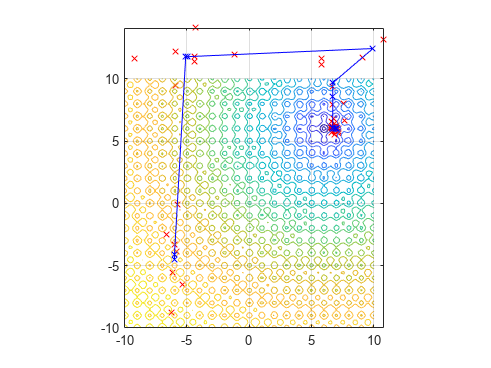

clear;clc;clf;

%% shifted ackley
shift = [6;6]; f = @(x) ackley(x-shift); f_grad = @(x) ackley_grad(x-shift); 
xs = linspace(-10,10); ys = linspace(-10,10); [Xs,Ys] = meshgrid(xs,ys);
for i=1:100
    for j=1:100
        Zs(i,j) = f([Xs(i,j),Ys(i,j)]');
    end
end
contour(Xs,Ys,Zs,0:50); hold on; grid on; axis equal; f1.Position = [397         155        1042         795];  plot3(shift(1),shift(2),0,'ko')

x0 = [-6;-4.5];  
plot3(x0(1,end),x0(2,end),0,'rx');

mesh_adapt(x0, f)

% cross_entry(x0, f)
% diff_evol(x0, f)
% part_swarm(x0, f)

function [val] = ackley(x)
a = 20; b = 0.2; c = 2*pi;
d = length(x);
val = -a*exp(-b*sqrt(sum(x.^2))/d) - exp(sum(cos(c*x))/d) + a + exp(1);
end

function [val] = ackley_grad(x)
a = 20; b = 0.2; c = 2*pi;
d = length(x); val = zeros(d,1);
for i=1:d
    val(i,1) = -a*exp(-b*sqrt(sum(x.^2))/d)*(-b*(1/(sqrt(sum(x.^2))/d))*2*x(i)/d) - exp(sum(cos(c*x))/d)*(-c*sin(c*x(i))/d);
end
end

function [D] = rand_positive_spanning_set(alpha, n)
delta = round(1/sqrt(alpha));
L = diag(delta*(2*rand(n,1)-1));
for i=1:n-1
    for j = i+1:n
        L(i,j)=(2*delta+2)*rand(1)-delta+1;
    end
end
D =L(:,randperm(n));
D=D(randperm(n),:);
D =[D,-sum(D,2)];
return 
end

function [val] = mesh_adapt(x0, f)
%% mesh adaptive search
xs = [x0]; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx')
iter = 1; alpha = 1; y=f(x0); n=length(x0); var_eps = 1e-6; x=x0;
while alpha > var_eps
    improved = false;
    D = rand_positive_spanning_set(alpha,n);
    plot3(xs(1,end)+alpha*D(1,:),xs(2,end)+alpha*D(2,:),zeros(1,n+1),'rx')
    for i = 1:3
        d = D(:,i);
        x_p = x+alpha*d; 
        y_p =f(x_p);
        if y_p < y
            x =x_p; y=y_p; improved = true;
            x_p = x+3*alpha*d; y_p = f(x_p);
            if y_p < y
                x = x_p; y = y_p;
            end
            break;
        end
    end
    if improved
        alpha = min(4*alpha,1);
    else
        alpha = alpha/4;
    end
    xs(:,end+1) = x;
    plot3([xs(1,end-1),xs(1,end)],[xs(2,end-1),xs(2,end)],[f(xs(:,end-1)), f(xs(:,end))],'b-x'); pause(0.1)
    iter = iter + 1;
    if iter > 100
        break;
    end
end
end

function [val] = cross_entry(x0, f)
%% cross-entry method
xs = [x0]; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx');
circ = [sin(linspace(0,2*pi));cos(linspace(0,2*pi))];
m = 40; k_max = 50; m_elite = 10;
mu = x0; sigma = 10*eye(2); R=chol(sigma);

for k = 1:k_max
    samples = (repmat(mu',m,1)+randn(m,2)*R)';
    points = plot3(samples(1,:),samples(2,:),zeros(1,m),'bx');

    circ2 = R*circ+mu;
    plot3(circ2(1,:),circ2(2,:),zeros(1,100),'g-','LineWidth',2,'MarkerSize',10);
    for i = 1:m
        y(i) = f(samples(:,i));
    end

    [y,s] = sort(y,"ascend"); 
    P = samples(:,s(1:m_elite));
%     plot3(P(1,:),P(2,:),zeros(1,m_elite),'bs','LineWidth',2,'MarkerSize',10);
    mu_new = (sum(P,2))/(m_elite);
    plot3([mu(1),mu_new(1)],[mu(2),mu_new(2)],zeros(1,2),'c-','LineWidth',2,'MarkerSize',10);
    mu = mu_new;
    sigma = cov(P'); 
    R=chol(sigma); pause(1);
    points.Visible = 'off';
end
end

function [val] = diff_evol(x0, f)
%% Differential evolution
m = 10;
pop = [x0+rand(2,m)]; k_max = 50; w = 0.8; p=0.9;
for i=1:m
    val(i)=f(pop(:,i));
end
for k = 1:k_max
    pop_plot = plot3(pop(1,:),pop(2,:),zeros(1,m),'rs','LineWidth',2,'MarkerSize',10);
    children = zeros(2,m);
    for i = 1:m
        perm = randperm(m,3);
        z = pop(:,perm(1))+w*(pop(:,perm(2))-pop(:,perm(3)));
        j = randperm(2,1);
        children(:,i) = pop(:,i);
        for d = 1:2
            if d == j || p < rand(1)
                children(d,i) = z(d);
            end
        end
    end
    for i = 1:m
        val_child = f(children(:,i));
        if val_child < val(i)
            pop(:,i) = children(:,i);
            val(i)=val_child;
        end
    end
    pause(0.1);
    pop_plot.Visible = 'off';
end
pop_plot = plot3(pop(1,:),pop(2,:),zeros(1,m),'rx','LineWidth',2,'MarkerSize',10);
end

function [val] = part_swarm(x0, f)
%% Particle swarm optimization,
m = 10;
pop = [x0+rand(2,m)]; k_max = 50; w = 0.9; c_1 =1.2; c_2 = 1.2; v(:,100)=x0;
for i=1:m
    val(i)=f(pop(:,i));
end
y_best_i = val; 
[minval, minpos] = min(val); 
y_best = minval;
x_best = pop(:,minpos);
x_best_i(:,i) = pop(:,i);
for i=1:m
    v(:,i)=w*v(:,i) + c_1*rand(1)*(x_best_i(:,i)-pop(:,i))+c_2*rand(1)*(x_best-pop(:,i));
end
for k = 1:k_max
    pop_plot = plot3(pop(1,:),pop(2,:),zeros(1,m),'rx','LineWidth',2,'MarkerSize',10);
    for i = 1:m
        pop(:,i) = pop(:,i)+v(:,i);
        v(:,i)=w*v(:,i) + c_1*rand(1)*(x_best_i(:,i)-pop(:,i))+c_2*rand(1)*(x_best-pop(:,i));
        val(i) = f(pop(:,i));
        if val(i) < y_best_i(i)
            y_best_i(i) = val(i); x_best_i(:,i) = pop(:,i);
        end
    end
    [minval, minpos] = min(val);
    if minval < y_best
        y_best = minval; x_best=pop(:,minpos);
    end
    pause(0.1);
    pop_plot.Visible = 'off';
end
pop_plot = plot3(pop(1,:),pop(2,:),zeros(1,m),'rx','LineWidth',2,'MarkerSize',10);
end